# Introduction to finite differences

clear, clc
set_defaults()

## One-sided approximation

In calculus the derivative of a function $f\left(x\right)$at $x_0$ is defined by the following limit

$\dot{f}=\left.\frac{\mathrm{d} f}{\mathrm{d} x}\right|_
{x_0} = \lim_{\Delta x\rightarrow 0} \frac{f(x_0+\Delta x)-f(x_0)}{\Delta x}$.

The finite difference approximation, $\hat{\dot{f}}$, of $\dot{f}$simply simply takes a finite $\Delta x$, corresponding to the grid spacing 


$$\hat{\dot{f}}_
{x_0} =\frac{f(x_0+\Delta x)-f(x_0)}{\Delta x} + \mathcal{O}(\Delta x)$$


where $\mathcal{O}$ is the order of the error between $\hat{\dot{f}}$and $\dot{f}$. As we increase the number of grid points, $\Delta x$ becomes smaller and the numerical approximation improves. Consider the example below.

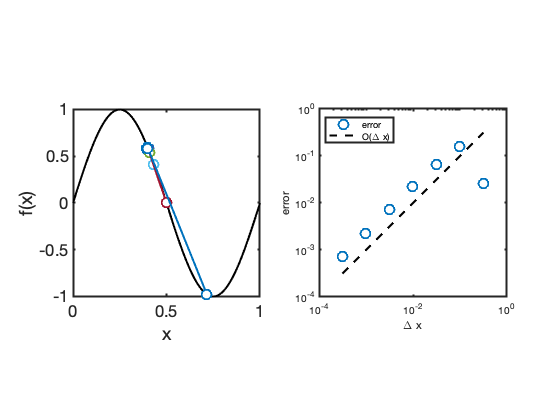

f = @(x) sin(2*pi*x);
dfdx = @(x) 2*pi*cos(2*pi*x);

x0 = .4;
dx_fd = logspace(log10(3.162e-4),log10(3.162e-1),7);
df_onesided = (f(x0+dx_fd) - f(x0))./dx_fd;

close all
subplot 121
x = linspace(0,1,1e2);
plot(x,f(x),'k-'), hold on
plot(x0,f(x0),'o','markerfacecolor','w')
xlabel 'x', ylabel 'f(x)'
pbaspect([1 1 1])

for i = 1:length(dx_fd)
    x0plus = x0+dx_fd(i);
    xx = [x0 x0plus];
    subplot 121
    plot(xx,f(xx),'o-','markerfacecolor','w','markersize',10)
end

subplot 122
error_onesided = abs(df_onesided - dfdx(x0))/abs(dfdx(x0));
loglog(dx_fd,error_onesided,'o','markerfacecolor','w','markersize',10), hold on
semilogy(dx_fd,dx_fd*1e0,'k--')
pbaspect([1 1 1])
xlabel '\Delta x', ylabel 'error'
legend('error','O(\Delta x)','location','northwest')

The error decreases linearly as $\Delta x$ declines. This one-sided difference is a first order approximation of the derivative. In the continouous defination of the derivative we don't care about the order of approximation, because in the limit of $\Delta x \rightarrow 0$ the approximation becomes exact.

## Central difference approximation

In a numerical simulation $\Delta x$ will always be finite and we will get better results if our approximation of the derivative is more accurate. It can be shown that the following central difference aproximation is second order accurate


$$\hat{\dot{f}}_
{x_0} =\frac{f(x_0+\Delta x)-f(x_0-\Delta x)}{2\Delta x} + \mathcal{O}(\Delta x^2)$$


It is simple to verify this computationally

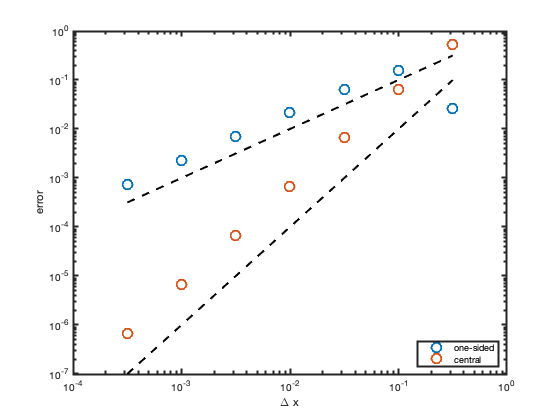

df_central = (f(x0+dx_fd) - f(x0-dx_fd))./(2*dx_fd);
error_central = abs(df_central - dfdx(x0))/abs(dfdx(x0));
figure
loglog(dx_fd,error_onesided,'o','markerfacecolor','w','markersize',10), hold on
loglog(dx_fd,error_central,'o','markerfacecolor','w','markersize',10)
semilogy(dx_fd,dx_fd*1e0,'k--')
semilogy(dx_fd,dx_fd.^(2)*1e0,'k--')
xlabel '\Delta x', ylabel 'error'
legend('one-sided','central','location','southeast')

The modeling of heat flow typically utilizes the central difference approximation, which is second-order accurate* in space*. Second-order accuracy is sufficient for most applications.

## Differentiation matrices

A linear differential operator $\mathcal{L}$ takes a function and returns a different functions (unless it is the identity operator). For example, the derivative operator $\dot{f} = \mathcal{D}(f)$. The discrete equivalent of a function is a vector, $\mathbf{f}$, that samples the function $f(\mathbf{x})$ at the discrete points $\mathbf{x}$. A discrete linear operator therefore takes a vector and returns a different vector, $\dot{\mathbf{f}} = \mathbf{D}\,\mathbf{f}$, and can therefore be represented by a matrix, $\mathbf{D}$. In the case of the derivative operator, we speak of a *differentiation matrix*.

In a straight finite difference implmentation we use central differences to construct this differentiation matrix. The n-th row of this matrix appies the central differentce stencil to the n-th element of the vector $\mathbf{f} = f(\mathbf{x})$. 

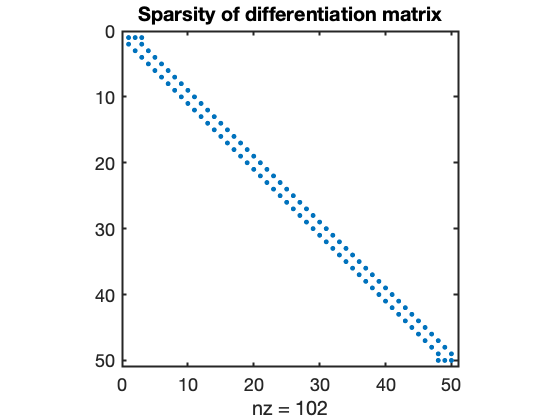

N = 50;
x = linspace(0,3,N)'; dx = x(2)-x(1);
e = ones(N,1); 
D = spdiags([-e e]/(2*dx),[-1 1],N,N); % Central difference in center of domain

D(1,[1 2 3]) = [-3 4 -1]/(2*dx);    % One-sided differences at left end
D(N,[N-2 N-1 N]) = [1 -4 3]/(2*dx); % One-sided differences at right end
figure
spy(D)
title 'Sparsity of differentiation matrix'

## Sparse banded matrices

The concept of a sparse matrix representation is crucial for efficient numerical implementation of PDE-base numerical models. The function [spy()](https://www.mathworks.com/help/matlab/ref/spy.html) shows the "sparsity pattern" of our differentiation matrix, i.e., all **non-zero** entries are shown as a dot. Clearly the differentiation matrix is mostly zeros. This is because the central difference approximation only involves the two neighboring grid-points. 

The idea of [sparse matrix representation](https://www.mathworks.com/help/matlab/sparse-matrices.html) is to avoid storing all th zeros, otherwise computations would quickly become limited by memory. For a sparse matrix we simply store the three numbers (i,j,value) for the non-zero elemnts. You never actually have to deal with this Matlab takes care of this, but you must use specific sparse matric functions to create your matrices. 

Differentiation matrices are typically banced, i.e., they have a few diagonals that contain most of the non-zero entries. In our example there are two non-zero diagonal, except for the first and the last row where one-sided approximations are required for points on the boundary. Sparse diagonal matrices are created with the function [spdiags()](https://www.mathworks.com/help/matlab/ref/spdiags.html), this function will become good friend of yours this semester - read the documentation.

Notice, there is also a function [diag()](https://www.mathworks.com/help/matlab/ref/diag.html) which creates full diagonal matrices, i.e., banded matrices where every elemnt is stored. In Matlab you often have a full and a sparse version of a function, the spars version is typically indicated by appending 'sp' to the function name. Never use diag() to create you matrices for this class. In fact, if you ever run out of memory in homworks for this class, you likely forgot to make a matrix sparse! 

Now we test if multilpying $\mathbf{D}$ by some vector $\mathbf{f}$ returns its derivative and if multiplying it twice with $\mathbf{B}$ returns the second derivative.

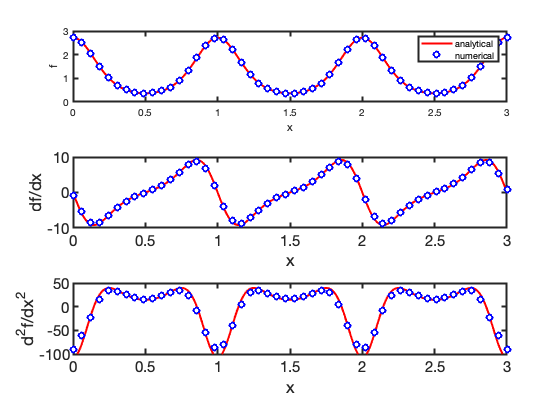

f = @(x) exp(cos(2*pi*x));
dfdx = @(x) -exp(cos(2*pi*x)).*sin(2*pi*x)*2*pi; 
d2fdx2 = @(x) -2*pi^2*exp(cos(2*pi*x)).*(2*cos(2*pi*x)+cos(4*pi*x)-1);

xa = linspace(0,3,3e2);
figure(2)
subplot 311
plot(xa,f(xa),'r',x,f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'f'
legend('analytical','numerical')

subplot 312
plot(xa,dfdx(xa),'r',x,D*f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'df/dx'

subplot 313
plot(xa,d2fdx2(xa),'r',x,D^2*f(x),'bo','markerfacecolor','w','markersize',6)
xlabel 'x', ylabel 'd^2f/dx^2'
ylim([-100 50])

## Convergence with grid refinement

To check the convergence of the discrete operators compute the error between $\partial f/\partial x$ and D`*f` and $\partial^2 f/\partial x^2$ and `D^2*f` as the number grid points increases. 

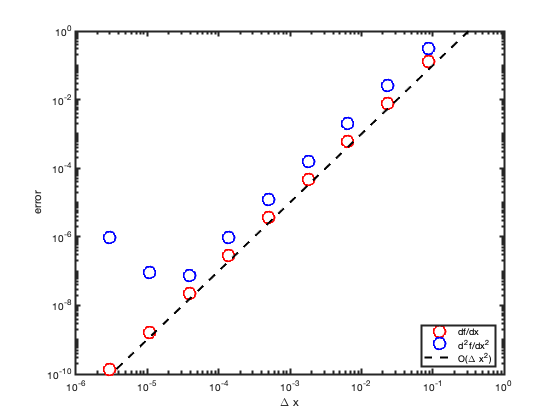

N = round(logspace(1,6,10));
for i = 1:length(N)
    [D,xc] = build_diff_matrix(N(i));
    error_dfdx(i) = norm(dfdx(xc)-D*f(xc))/norm(dfdx(xc));
    error_d2fdx2(i) = norm(d2fdx2(xc)-D^2*f(xc))/norm(d2fdx2(xc));
    dxc(i) = xc(2)-xc(1);
end

figure
loglog(dxc,error_dfdx,'ro','markerfacecolor','w'), hold on
loglog(dxc,error_d2fdx2,'bo','markerfacecolor','w')
semilogy(dxc,dxc.^(2)*1e1,'k--')
xlabel '\Delta x', ylabel 'error'
ylim([1e-10 1])
legend('df/dx','d^2f/dx^2','O(\Delta x^2)','location','southeast')
pbaspect([1 .8 1])

The graph shows that both first and second derivatives converge with 2-nd order accuracy. In general, the error increases with the order of the derivative, because error from the first application of D is compounded. The increase of the error in the second derivative at very small Dx is due to rounding error. In practical simulation, this won't be a problem as grids are generally too coarse rather than too fine.

## Auxillary functions

function [] = set_defaults()
    set(0, ...
    'defaultaxesfontsize',   18, ...
    'defaultaxeslinewidth',   2.0, ...
    'defaultlinelinewidth',   2.0, ...
    'defaultpatchlinewidth',  2.0,...
    'DefaultLineMarkerSize', 12.0);
end

Functions that builds the differentiation matrix

function [D,x] = build_diff_matrix(N)
    x = linspace(0,3,N)'; dx = x(2)-x(1);
    e = ones(N,1);
    D = spdiags([-e e]/(2*dx),[-1 1],N,N); % Central difference in center of domain
    
    D(1,[1 2 3]) = [-3 4 -1]/(2*dx);       % One-sided differences at left end
    D(N,[N-2 N-1 N]) = [1 -4 3]/(2*dx);    % One-sided differences at right end
end